# BUCK CONVERTER — Modello matematico completo

### **PARTE 1 :**

**Riferimento**: *Lena, Setti, Pareschi* 

## Setup iniziale

clear; close all; clc;

fprintf('=================================================================\n');

fprintf(' BUCK CONVERTER — Modello matematico completo\n');

 BUCK CONVERTER — Modello matematico completo


fprintf(' Ref: Lena, Setti, Pareschi et al., arXiv:2509.02102v1\n');

 Ref: Lena, Setti, Pareschi et al., arXiv:2509.02102v1


fprintf('=================================================================\n\n');

## Sezione 1.1 — Parametri nominali 

In questa sezione definiamo i componenti fisici del power stage, i parametri di sistema e le incertezze relative associate a ciascun componente.

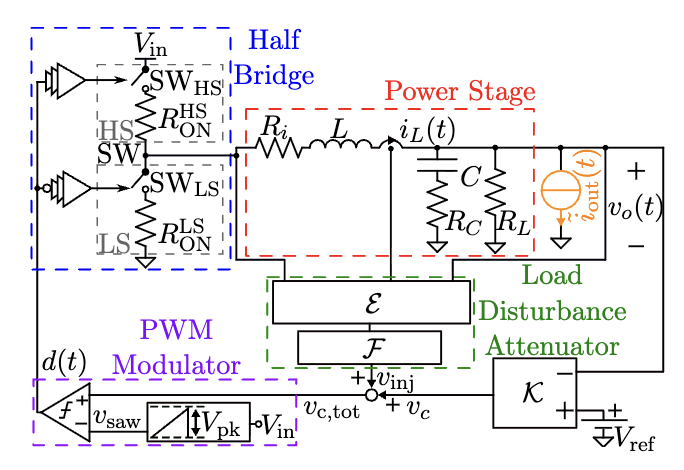

fprintf('--- SEZIONE 1: Parametri nominali (Tabella 1) ---\n');

--- SEZIONE 1: Parametri nominali (Tabella 1) ---



% --- Componenti del Power Stage ---
C     = 0.249e-3;   % [F]    Condensatore di uscita 
L     = 8.2e-6;     % [H]    Induttore 
R_c   = 0.115e-3;   % [Ohm]  ESR condensatore 
R_i   = 7e-3;       % [Ohm]  Resistenza avvolgimento induttore 
R_ON  = 6.5e-3;     % [Ohm]  R_ON^{HS,LS} MOSFET 

% --- Parametri di sistema ---
f_sw      = 500e3;      % [Hz]     Frequenza di switching
omega_sw  = 2*pi*f_sw;  % [rad/s]
k_FF      = 30;         % [-]      Costante feedforward PWM
V_target  = 5.0;        % [V]      Tensione di uscita target
I_max     = 10.0;       % [A]      Corrente massima di uscita
V_in_max  = 20.0;       % [V]      Tensione massima di ingresso

% --- Incertezze relative (per uso futuro in mu-analysis) ---
delta_C   = 0.10;  % +10%
delta_L   = 0.20;  % +20%
delta_Rc  = 0.15;  % +15%
delta_Ri  = 0.15;  % ±15%
delta_RON = 0.15;  % ±15%

fprintf('  C     = %.4f mF\n',   C*1e3);

  C     = 0.2490 mF


fprintf('  L     = %.2f uH\n',   L*1e6);

  L     = 8.20 uH


fprintf('  R_c   = %.4f mOhm (ESR condensatore)\n',        R_c*1e3);

  R_c   = 0.1150 mOhm (ESR condensatore)


fprintf('  R_i   = %.2f mOhm (resistenza avvolgimento)\n', R_i*1e3);

  R_i   = 7.00 mOhm (resistenza avvolgimento)


fprintf('  R_ON  = %.2f mOhm (MOSFET ON resistance)\n',    R_ON*1e3);

  R_ON  = 6.50 mOhm (MOSFET ON resistance)


fprintf('  f_sw  = %.0f kHz\n', f_sw/1e3);

  f_sw  = 500 kHz


fprintf('  k_FF  = %d\n',       k_FF);

  k_FF  = 30


fprintf('  V_target = %.1f V\n', V_target);

  V_target = 5.0 V


fprintf('\n'); 

## Sezione 1.2 — Intervallo di carico R_L (eq. 1)

Garantisce il funzionamento in CCM (Continuous Conduction Mode).


$$R_{L,min} = \frac{V_{target}}{I_{max}}$$



$$R_{L,max} = \frac{2 * L_{min} f_{sw}}{1 - \frac{V_{target}}{V_{in,max}}}$$


fprintf('--- SEZIONE 1.2: Intervallo di carico R_L (eq. 1) ---\n');

--- SEZIONE 1.2: Intervallo di carico R_L (eq. 1) ---



L_min   = L * (1 - delta_L);       % L con incertezza massima negativa
R_L_min = V_target / I_max;        % Limite inferiore (corrente massima)
R_L_max = (2 * L_min * f_sw) / ...
    (1 - V_target / V_in_max); % Limite superiore (garantisce CCM)

% Valore nominale: media geometrica dell'intervallo
R_L = sqrt(R_L_min * R_L_max);

fprintf('  L_min    = %.4f uH (L con incertezza -20%%)\n', L_min*1e6);

  L_min    = 6.5600 uH (L con incertezza -20%)


fprintf('  R_L_min  = V_target/I_max = %.4f Ohm\n', R_L_min);

  R_L_min  = V_target/I_max = 0.5000 Ohm


fprintf('  R_L_max  = 2*L_min*f_sw/(1-V_target/V_in_max) = %.4f Ohm\n', R_L_max);

  R_L_max  = 2*L_min*f_sw/(1-V_target/V_in_max) = 8.7467 Ohm


fprintf('  R_L nom  = sqrt(R_L_min * R_L_max) = %.4f Ohm\n', R_L);

  R_L nom  = sqrt(R_L_min * R_L_max) = 2.0913 Ohm


fprintf('  Intervallo I_R_L = [%.4f, %.4f] Ohm\n', R_L_min, R_L_max);

  Intervallo I_R_L = [0.5000, 8.7467] Ohm


fprintf('\n');

## Sezione 1.3 — Parametri derivati (eq. 13)

Resistenza serie equivalente e resistenza parallelo equivalente:


$$R'_i = R_i + R_{ON}^{HS,LS}$$



$$R'_c = R_L + R_c$$


Coefficienti del denominatore comune $D(s) = a_0 s^2 + a_1 s + a_2$:


$$a_0 = C \, L \, (R_L + R_c)$$



$$a_1 = L + C R_L (R_C + R'_i) + C R_C R'_i$$


 
$$a_2 =R_L +R\prime_i$$


fprintf('--- SEZIONE 1.3: Parametri derivati e coefficienti (eq. 13) ---\n');

--- SEZIONE 1.3: Parametri derivati e coefficienti (eq. 13) ---



% Resistenze equivalenti
R_i_prime = R_i + R_ON;   % R'_i = R_i + R_ON [Ohm]
R_c_prime = R_L + R_c;    % R'_c = R_L + R_c [Ohm]

% Coefficienti denominatore comune D(s)
a0 = C * L * (R_L + R_c);
a1 = (L + C*R_L*(R_c + R_i_prime) + C*R_c*R_i_prime);
a2 = R_L + R_i_prime ;

fprintf('  R_i_prime = R_i + R_ON = %.4f mOhm\n', R_i_prime*1e3);

  R_i_prime = R_i + R_ON = 13.5000 mOhm


fprintf('  R_c_prime = R_L + R_c = %.6f Ohm\n', R_c_prime);

  R_c_prime = R_L + R_c = 2.091367 Ohm


fprintf('\n');
fprintf('  Coefficienti denominatore D(s) = a0*s^2 + a1*s + a2:\n');

  Coefficienti denominatore D(s) = a0*s^2 + a1*s + a2:


fprintf('  a0 = C*L*(R_L+R_c) = %.6e\n', a0);

  a0 = C*L*(R_L+R_c) = 4.270152e-09


fprintf('  a1 = L + C*R_c*(R_L+R_i'') + C*R_L*R_i'' = %.6e\n', a1);

  a1 = L + C*R_c*(R_L+R_i') + C*R_L*R_i' = 1.529001e-05


fprintf('  a2 = R_L + R_i'' + R_c = %.6f Ohm\n', a2);

  a2 = R_L + R_i' + R_c = 2.104752 Ohm


fprintf('\n');

% Denominatore comune come polinomio [a0, a1, a2]
den = [a0, a1, a2];

## Sezione 2 — Modello lineare PWM + Half Bridge (eq. 9-10)

Modello nonlineare :


$$\[
d(t)=
\begin{cases}
0, & \text{se } v_c(t) < v_{saw}(t),\\
1, & \text{altrimenti.}
\end{cases}
\]$$


Sotto Assunzioni 1-2 (piccolo segnale, banda < f_sw), con feedforward $V_{pk} = \frac{V_{in}}{k_{FF}}$ (eq. 10):


$$v_{SW}(t) = k_{FF} \, v_c(t) + d_a(t)$$


Guadagno PWM (costante, indipendente da $V_{in}$):


$$G_{PWM} = k_{FF} = 30$$


fprintf('--- SEZIONE 2: Modello lineare PWM + Half Bridge (eq. 10) ---\n');

--- SEZIONE 2: Modello lineare PWM + Half Bridge (eq. 10) ---



G_PWM = k_FF;   % Guadagno PWM con feedforward 

% Come tf MATLAB: guadagno puro (nessuna dinamica)
PWM_tf = tf(G_PWM, 1);

fprintf('  Guadagno PWM con feedforward:\n');

  Guadagno PWM con feedforward:


fprintf('  G_PWM = k_FF = %d (indipendente da V_in)\n', G_PWM);

  G_PWM = k_FF = 30 (indipendente da V_in)


fprintf('  Modello: v_SW(s) = k_FF * v_c(s) = %d * v_c(s)\n', k_FF);

  Modello: v_SW(s) = k_FF * v_c(s) = 30 * v_c(s)


fprintf('\n');

## Sezione 2.1 — Power Stage: matrice P(s) (eq. 11-12)


$$\left[
\matrix{
v_o(s) \cr
i_L(s)
}
\right]
=
\left[
\matrix{
P_{11}(s) & P_{12}(s) \cr
P_{21}(s) & P_{22}(s)
}
\right]
\left[
\matrix{
v_{SW}(s) \cr
\hat{i}_{out}(s)
}
\right]$$



$$P_{11}(s)=\frac{R_L\left(1+C R_c s\right)}{D(s)}
=
P_{22}(s)
\qquad
(\mathrm{eq.\ 12a})$$



$$P_{12}(s)=
\frac{R_L\left[-C L R_c s^2-\left(L+C R_c R'_i\right)s-R'_i\right]}
{D(s)}
\qquad
(\mathrm{eq.\ 12b})$$



$$P_{21}(s)=
\frac{C\left(R_L+R_c\right)s+1}
{D(s)}
\qquad
(\mathrm{eq.\ 12c})$$


fprintf('--- SEZIONE 2.1: Power Stage P(s) ---\n');

--- SEZIONE 2.1: Power Stage P(s) ---



num_P11 = R_L * [C*R_c, 1];
P11 = tf(num_P11, den);
P22 = P11;   % P11 = P22

fprintf('  P11(s) = P22(s) = v_o(s)/v_SW(s):\n');

  P11(s) = P22(s) = v_o(s)/v_SW(s):


fprintf('  Num = R_L*(C*R_c*s + 1) = [%.4e, %.4f]\n', num_P11(1), num_P11(2));

  Num = R_L*(C*R_c*s + 1) = [5.9883e-08, 2.0913]


fprintf('  DC gain P11(0) = R_L/a2 = %.6f\n', R_L/a2);

  DC gain P11(0) = R_L/a2 = 0.993586



z_ESR = -1/(C*R_c);
f_ESR = abs(z_ESR)/(2*pi);
fprintf('  Zero ESR: z1 = -1/(C*R_c) = %.4e rad/s => f = %.2f kHz\n', ...
    z_ESR, f_ESR/1e3);

  Zero ESR: z1 = -1/(C*R_c) = -3.4922e+07 rad/s => f = 5558.06 kHz


fprintf('\n');


num_P12 = R_L * [-C*L*R_c, -(L + C*R_c*R_i_prime), -R_i_prime];
P12 = tf(num_P12, den);

fprintf('  P12(s) = v_o(s)/i_out_hat(s) [impedenza uscita]:\n');

  P12(s) = v_o(s)/i_out_hat(s) [impedenza uscita]:


fprintf('  Num = R_L*[-C*L*R_c*s^2 - (L+C*R_c*R_ip)*s - R_ip]\n');

  Num = R_L*[-C*L*R_c*s^2 - (L+C*R_c*R_ip)*s - R_ip]


fprintf('      = [%.4e, %.4e, %.6f]\n', num_P12(1), num_P12(2), num_P12(3));

      = [-4.9104e-13, -1.7149e-05, -0.028232]


fprintf('  DC gain P12(0) = -R_L*R_ip/a2 = %.6f Ohm\n', -R_L*R_i_prime/a2);

  DC gain P12(0) = -R_L*R_ip/a2 = -0.013413 Ohm


fprintf('\n');


num_P21 = [C*(R_L + R_c), 1];
P21 = tf(num_P21, den);

fprintf('  P21(s) = i_L(s)/v_SW(s):\n');

  P21(s) = i_L(s)/v_SW(s):


fprintf('  Num = C*(R_L+R_c)*s + 1 = [%.4e, 1]\n', num_P21(1));

  Num = C*(R_L+R_c)*s + 1 = [5.2075e-04, 1]


fprintf('  DC gain P21(0) = 1/a2 = %.4f A/V\n', 1/a2);

  DC gain P21(0) = 1/a2 = 0.4751 A/V


fprintf('\n');

## Sezione 2.2 — FdT open-loop G(s) = k_FF * P11(s) (eq. 14)


$$G^{v_o}_{v_c}(s) = \frac{v_o(s)}{v_c(s)} = k_{FF} \, P_{11}(s)$$


Questa è la FdT di piccolo segnale dell'intera pianta (PWM + HB + PS) usata come base per il progetto di K.

fprintf('--- SEZIONE 2.2: FdT open-loop G(s) = k_FF * P11(s) (eq. 14) ---\n');

--- SEZIONE 2.2: FdT open-loop G(s) = k_FF * P11(s) (eq. 14) ---



G = G_PWM * P11;   % G(s) = k_FF * P11(s)
% Coefficienti espliciti
num_G = k_FF * num_P11;   % [k_FF*R_L*C*R_c, k_FF*R_L]

fprintf('  G(s) = k_FF * P11(s):\n');

  G(s) = k_FF * P11(s):


fprintf('  Num = [%.4e, %.4f]\n', num_G(1), num_G(2));

  Num = [1.7965e-06, 62.7375]


fprintf('  Den = [%.4e, %.4e, %.4f]\n', den(1), den(2), den(3));

  Den = [4.2702e-09, 1.5290e-05, 2.1048]


fprintf('\n');

% Proprietà
DC_gain_G = dcgain(G);
fprintf('  Proprieta'' di G(s):\n');

  Proprieta' di G(s):


fprintf('  Guadagno DC G(0) = k_FF * R_L/a2 = %.4f\n', DC_gain_G);

  Guadagno DC G(0) = k_FF * R_L/a2 = 29.8076


fprintf('  Zero ESR: f_ESR = %.2f kHz (fuori banda, trascurabile)\n', f_ESR/1e3);

  Zero ESR: f_ESR = 5558.06 kHz (fuori banda, trascurabile)


fprintf('\n');

% Poli di G(s) = poli di P11(s) = radici del denominatore
poli_G = pole(G);
fprintf('  Poli di G(s):\n');

  Poli di G(s):


for k = 1:length(poli_G)
    if imag(poli_G(k)) ~= 0
        fprintf('    p%d = %.4f + j*%.4f rad/s\n', k, real(poli_G(k)), imag(poli_G(k)));
    else
        fprintf('    p%d = %.4f rad/s\n', k, real(poli_G(k)));
    end
end

    p1 = -1790.3356 + j*22129.0122 rad/s
    p2 = -1790.3356 + j*-22129.0122 rad/s



% Frequenze caratteristiche del Power Stage
omega_PS = sqrt(a2/a0);          % pulsazione naturale [rad/s]
f_PS     = omega_PS/(2*pi);      % frequenza naturale [Hz]
zeta_PS  = (a1/(2*sqrt(a0*a2)));   % smorzamento

fprintf('\n  Frequenze caratteristiche del Power Stage:\n');


  Frequenze caratteristiche del Power Stage:


fprintf('  omega_PS = sqrt(a2/a0) = %.4f rad/s\n', omega_PS);

  omega_PS = sqrt(a2/a0) = 22201.3171 rad/s


fprintf('  f_PS = omega_PS/(2*pi) = %.4f Hz (~%.2f kHz)\n', f_PS, f_PS/1e3);

  f_PS = omega_PS/(2*pi) = 3533.4494 Hz (~3.53 kHz)


fprintf('  zeta_PS = a1/(2*sqrt(a0*a2)) = %.6f\n', zeta_PS);

  zeta_PS = a1/(2*sqrt(a0*a2)) = 0.080641


fprintf('  omega_ESR = 1/(C*R_c) = %.4e rad/s => f_ESR = %.2f kHz\n', ...
    abs(z_ESR), f_ESR/1e3);

  omega_ESR = 1/(C*R_c) = 3.4922e+07 rad/s => f_ESR = 5558.06 kHz


fprintf('\n');
%per visualizzare la funzione di trasferimento
zpk(G)


ans =
 
    420.71 (s+3.492e07)
  ------------------------
  (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.


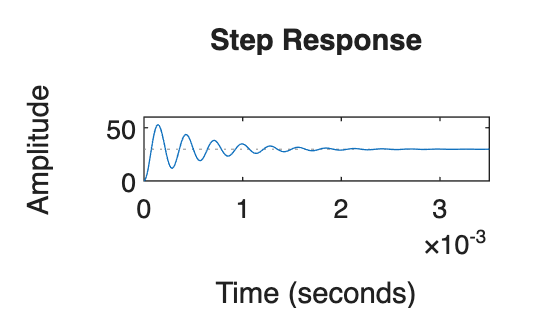

figure;
step(G);

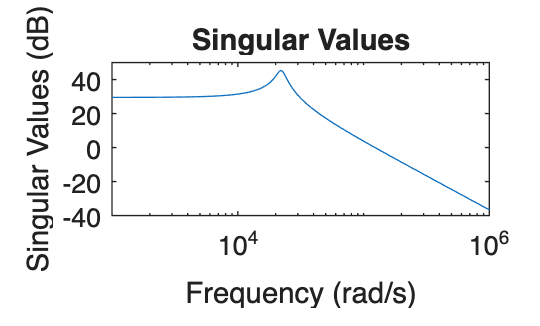

Gjw = squeeze(freqresp(G, omega_PS));
[Y, S, U] = svd(Gjw);
sigma_max = S(1,1);                           
figure;
sigma(G)

sigma_max_dB = 20*log10(sigma_max);
fprintf('SVD max: %.4f\n', sigma_max)          

SVD max: 184.8166


fprintf('SVD max in dB: %.4f\n', sigma_max_dB) 

SVD max in dB: 45.3348


norm(G, 'Inf')

ans = 185.4205

## Sezione 2.3— Vettore di frequenze per i grafici di Bode

Vettore di frequenze usato per i diagrammi di Bode/sigma, da 10 Hz fino a 5 volte la frequenza di switching.

f_vec = logspace(1, log10(5*f_sw), 2000);
omega_vec = 2*pi*f_vec;

## Sezione 2.4— Famiglia incerta: ureal + ucover

**Passo 1: costruzione della famiglia di impianti **$G_i (s)$

Per ogni combinazione degli estremi dei parametri incerti $\left(L,C,R_i ,R_c ,R_{\mathrm{ON}} \right)\;$si calcola una realizzazione di G(s). 

**Passo 2: modello incerto con ureal**

Si definisce $G_{\textrm{unc}} \left(s\right)$ come sistema con parametri ureal — oggetto nativo del Robust Control Toolbox di MATLAB che rappresenta l'incertezza strutturata parametrica.

fprintf('--- SEZIONE 2.4: Famiglia incerta e ucover ---\n');

--- SEZIONE 2.4: Famiglia incerta e ucover ---



% --- PASSO 1: Campionamento del polytope di incertezza ---
% Estremi di ogni parametro (±incertezza nominale)
L_vals   = [L*(1-delta_L),   L*(1+delta_L)  ];   % [L_min, L_max]
C_vals   = [C*(1-delta_C),   C*(1+delta_C)  ];
Ri_vals  = [R_i*(1-delta_Ri), R_i*(1+delta_Ri)];
Rc_vals  = [R_c*(1-delta_Rc), R_c*(1+delta_Rc)];
RON_vals = [R_ON*(1-delta_RON),R_ON*(1+delta_RON)];

% Funzione locale: calcola G(s) per dati parametri
function Gk = build_G(Lk, Ck, Rik, Rck, RONk, R_L, k_FF)
    Ripk = Rik + RONk;
    a0k  = Ck*Lk*(R_L + Rck);
    a1k  = Lk + Ck*R_L*(Rck+Ripk) + Ck*Rck*Ripk;
    a2k  = R_L + Ripk;
    num  = k_FF * R_L * [Ck*Rck, 1];
    den  = [a0k, a1k, a2k];
    Gk   = tf(num, den);
end

% Vertici del polytope (2^5 = 32 combinazioni)
params = {L_vals, C_vals, Ri_vals, Rc_vals, RON_vals};
n_params = numel(params);
n_vert   = 2^n_params;   % 32 vertici
G_array  = cell(n_vert, 1);

for idx = 1:n_vert
    bits = dec2bin(idx-1, n_params) - '0';   % vettore binario [0/1]
    Lk   = params{1}(bits(1)+1);
    Ck   = params{2}(bits(2)+1);
    Rik  = params{3}(bits(3)+1);
    Rck  = params{4}(bits(4)+1);
    RONk = params{5}(bits(5)+1);
    G_array{idx} = build_G(Lk, Ck, Rik, Rck, RONk, R_L, k_FF);
end

% Stack come array di FdT (richiesto da ucover)
G_stack = stack(1, G_array{:});
G0      = G;   % impianto nominale

fprintf('  Famiglia generata: %d vertici del polytope di incertezza\n', n_vert);

  Famiglia generata: 32 vertici del polytope di incertezza


fprintf('  Parametri variati: L(±%.0f%%), C(±%.0f%%), Ri(±%.0f%%), Rc(±%.0f%%), RON(±%.0f%%)\n', ...
        delta_L*100, delta_C*100, delta_Ri*100, delta_Rc*100, delta_RON*100);

  Parametri variati: L(±20%), C(±10%), Ri(±15%), Rc(±15%), RON(±15%)



% --- PASSO 2: Sistema incerto con ureal in SPAZIO DI STATO (Ottimizzato per M11) ---

% I tuoi parametri ureal originali
L_u   = ureal('L_u',   L,   'Range', L_vals);
C_u   = ureal('C_u',   C,   'Range', C_vals);
Ri_u  = ureal('Ri_u',  R_i, 'Range', Ri_vals);
Rc_u  = ureal('Rc_u',  R_c, 'Range', Rc_vals);
RON_u = ureal('RON_u', R_ON,'Range', RON_vals);

% Invece di far calcolare a MATLAB 1/L_u direttamente nelle matrici, 
% definiamo l'inverso mediante la relazione algebrica ben condizionata:
Rip_u  = Ri_u + RON_u;
R_eq_u = R_L / (R_L + Rc_u);

% Inversi espliciti per la matrice di stato
invL_u = 1 / L_u;
invC_u = 1 / C_u;

% Assemblaggio delle matrici di stato in forma esplicita
A_u = [ -(Rip_u + Rc_u*R_eq_u) * invL_u,  -R_eq_u * invL_u ;
         R_eq_u * invC_u,                 -invC_u / (R_L + Rc_u) ];

B_u = [ k_FF * invL_u ; 
        0 ];

C_u_mat = [ Rc_u * R_eq_u,  R_eq_u ];
D_u     = 0;

% Creazione del modello State-Space incerto
G_unc_ss = ss(A_u, B_u, C_u_mat, D_u);

% Riduzione dell'ordine LFT (ELIMINA I BLOCCHI RIDONDANTI che gonfiano M11)
G_unc_use = simplify(G_unc_ss, 'Full');

## Sezione 2.5 — Definizione pesi W1(s) e W2(s) con makeweight

Makeweight(DC, fc, HF) costruisce un peso del primo ordine con:

- guadagno a bassa frequenza (DC) [lin, non dB]

- frequenza di crossover (fc) [rad/s]

- guadagno ad alta frequenza (HF) [lin, non dB]

La forma è: $W(s) = \frac{s/M + w_0}{s + w_0 \varepsilon}$ con $M = DC$, $\varepsilon = HF$, $w_0 = fc$.

**Logica di taratura (coerente con eq. 25 del paper)**

$W_1(s)$ agisce su S: $|S(j\omega)| < \frac{1}{|W_1(j\omega)|}$

$W_2(s)$ agisce su T: $|T(j\omega)| < \frac{1}{|W_2(j\omega)|}$


fprintf('--- Pesi We, Wd, Wn, Wu ---\n');

--- Pesi We, Wd, Wn, Wu ---


omegac = 2*pi*50e3;
% We: errore, passa-basso (S). |We|=1 a We_fc; We_DC alto 
We_DC  = 100;
We_fc  = 2*pi*2e3;        % [rad/s]  2 kHz (sotto la risonanza LC, ~3.5 kHz)
We_Ms  = 1.5;             % picco di S ammesso
We_HF  = 1/We_Ms;         % = 0.667
We     = makeweight(We_DC, We_fc, We_HF);
 
% Wd: disturbo in ingresso

Wd_DC  = 1;
Wd_HF  = 0.05;
Wd_fc  = 2*pi*10e3;        % [rad/s]
Wd_MAG = 1/sqrt(2);        
Wd     = makeweight(Wd_DC, [Wd_fc, Wd_MAG], Wd_HF);


% Wn: rumore di misura, passa-alto (shape dello spettro del rumore)
Wn_DC  = 0.1;
Wn_HF  = 0.6;
Wn_fc  = 2*pi*150e3;      % [rad/s]  150 kHz
Wn_MAG = sqrt(Wn_DC*Wn_HF);          % mag tra DC e HF (entrambi < 1)
Wn     = makeweight(Wn_DC, [Wn_fc, Wn_MAG], Wn_HF);
 
% Wu: sforzo di controllo, passa-alto (K*S)
Wu_DC  = 0.01;
Wu_HF  = 0.1;            
Wu_fc  = 2*pi*200e3;       
Wu_MAG = sqrt(Wu_DC*Wu_HF);
Wu     = makeweight(Wu_DC, [Wu_fc, Wu_MAG], Wu_HF);


## Sezione 3 - Controllo $H_{\infty }$

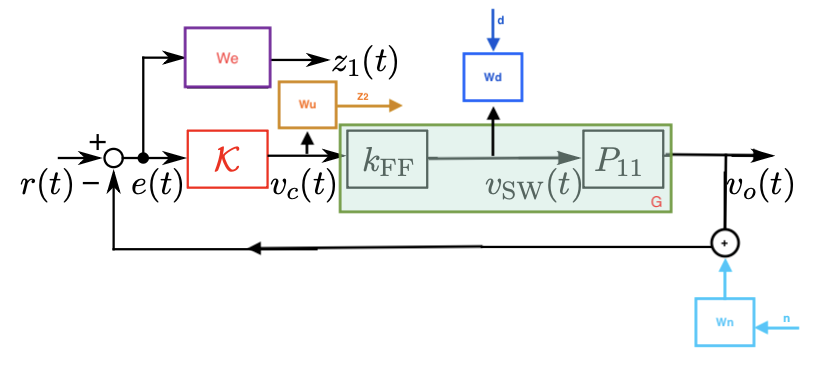

fprintf('--- SEZIONE 3: Generalized plant (4 pesi) con connect ---\n');

--- SEZIONE 3: Generalized plant (4 pesi) con connect ---



% --- Blocchi con segnali nominati ---
G_named = G;                          % G(s) = k_FF*P11(s)
G_named.InputName  = 'u_tot';
G_named.OutputName = 'y';

Wd_named = Wd;
Wd_named.InputName  = 'dhat';
Wd_named.OutputName = 'd';

Wn_named = Wn;
Wn_named.InputName  = 'nhat';
Wn_named.OutputName = 'n';

We_named = We;
We_named.InputName  = 'e';
We_named.OutputName = 'ze';

Wu_named = Wu;
Wu_named.InputName  = 'u';
Wu_named.OutputName = 'zu';

% --- Nodi di somma ---
Sum_utot = sumblk('u_tot = u + d');   % disturbo sommato all'ingresso del processo
Sum_ym   = sumblk('ym = y + n');      % rumore sommato in uscita (misura)
Sum_e    = sumblk('e = r - ym');      % errore


### Generazione automatica della matrice P con connect

% --- Interconnessione automatica ---
P_gen_connect_4w = connect(G_named, Wd_named, Wn_named, We_named, Wu_named, ...
    Sum_utot, Sum_ym, Sum_e, ...
    {'dhat','nhat','r','u'}, {'ze','zu','e'});

P_gen_connect_4w_mr = minreal(P_gen_connect_4w, [], false);

fprintf('  Generalized plant (4 pesi) costruita con connect: %d input, %d output\n', ...
    size(P_gen_connect_4w,2), size(P_gen_connect_4w,1));

  Generalized plant (4 pesi) costruita con connect: 4 input, 3 output


P_gen_connect_4w_mr


P_gen_connect_4w_mr =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1       -3581  -3.008e+04   2.382e+05           0           0           0
   x2   1.638e+04           0           0           0           0           0
   x3           0           0  -6.267e+04           0           0           0
   x4           0           0           0  -2.309e+06           0           0
   x5      -52.59  -1.121e+05           0   1.443e+05      -93.67           0
   x6           0           0           0           0           0  -3.974e+06
 
  B = 
        dhat   nhat      r      u
   x1   51.2      0      0   1024
   x2      0      0      0      0
   x3    256      0      0      0
   x4      0   1024      0      0
   x5      0  -76.8    128      0
   x6      0      0      0    512
 
  C = 
            x1       x2       x3       x4       x5       x6
   ze  -0.2739   -583.8        0    751.5    72.69        0
   zu        0        0        0        0     

### Realizzazioni individuali di P_MANUAL

fprintf('--- SEZIONE 3bis: Generalized plant (4 pesi) manuale ---\n');

--- SEZIONE 3bis: Generalized plant (4 pesi) manuale ---



% --- Realizzazioni minime individuali ---
Gss  = ss(minreal(G,  1e-6));
Wdss = ss(minreal(Wd, 1e-6));
Wnss = ss(minreal(Wn, 1e-6));
Wess = ss(minreal(We, 1e-6));
Wuss = ss(minreal(Wu, 1e-6));

[Ag,  Bg,  Cg,  Dg ] = ssdata(Gss);
[Awd, Bwd, Cwd, Dwd] = ssdata(Wdss);
[Awn, Bwn, Cwn, Dwn] = ssdata(Wnss);
[Awe, Bwe, Cwe, Dwe] = ssdata(Wess);
[Awu, Bwu, Cwu, Dwu] = ssdata(Wuss);

nG  = size(Ag,1);
nWd = size(Awd,1);
nWn = size(Awn,1);
nWe = size(Awe,1);
nWu = size(Awu,1);

% Stato x = [xG; xWd; xWn; xWe; xWu]

% --- Blocco A ---
A = [ Ag,             Bg*Cwd,              zeros(nG,nWn),   zeros(nG,nWe),  zeros(nG,nWu);
      zeros(nWd,nG),  Awd,                 zeros(nWd,nWn),  zeros(nWd,nWe), zeros(nWd,nWu);
      zeros(nWn,nG),  zeros(nWn,nWd),      Awn,             zeros(nWn,nWe), zeros(nWn,nWu);
     -Bwe*Cg,        -Bwe*Dg*Cwd,         -Bwe*Cwn,         Awe,            zeros(nWe,nWu);
      zeros(nWu,nG),  zeros(nWu,nWd),      zeros(nWu,nWn),  zeros(nWu,nWe), Awu ];

% --- Blocco B: ingressi [dhat, nhat, r, u] ---
B = [ Bg*Dwd,             zeros(nG,1),   zeros(nG,1),  Bg;
      Bwd,                zeros(nWd,1),  zeros(nWd,1), zeros(nWd,1);
      zeros(nWn,1),       Bwn,           zeros(nWn,1), zeros(nWn,1);
     -Bwe*Dg*Dwd,        -Bwe*Dwn,       Bwe,          -Bwe*Dg;
      zeros(nWu,1),       zeros(nWu,1),  zeros(nWu,1), Bwu ];

% --- Blocco C: uscite [ze, zu, e] ---
C_ind = [ -Dwe*Cg,   -Dwe*Dg*Cwd,   -Dwe*Cwn,   Cwe,             zeros(1,nWu);
           zeros(1,nG), zeros(1,nWd), zeros(1,nWn), zeros(1,nWe), Cwu;
          -Cg,        -Dg*Cwd,      -Cwn,        zeros(1,nWe),   zeros(1,nWu) ];

% --- Blocco D ---
D = [ -Dwe*Dg*Dwd,  -Dwe*Dwn,   Dwe,  -Dwe*Dg;
       0,             0,         0,    Dwu;
      -Dg*Dwd,       -Dwn,       1,   -Dg ];

P_manual_4w_ss = ss(A,B,C_ind,D);
P_manual_4w_ss.InputName  = {'dhat','nhat','r','u'};
P_manual_4w_ss.OutputName = {'ze','zu','e'};

fprintf('order(P_manual_4w_ss) = %d\n', order(P_manual_4w_ss));   % atteso: nG+nWd+nWn+nWe+nWu

order(P_manual_4w_ss) = 6


P_bd = [ -We*G*Wd,  -We*Wn,   We,   -We*G ;
    0,         0,        0,    Wu   ;
    -G*Wd,     -Wn,      1,    -G   ];

P_bd.InputName  = {'dhat','nhat','r','u'};
P_bd.OutputName = {'ze','zu','e'};
P_bd_mr = minreal(ss(P_bd));

11 states removed.


order(P_bd_mr)                                   % dovrebbe scendere a nG+nWd+nWn+nWe+nWu

ans = 6

% Confronto element-wise tra la versione connect e quella manuale
diff_4w = P_gen_connect_4w_mr - P_manual_4w_ss;
fprintf('norm(diff_4w, Inf) = %.4e\n', norm(diff_4w, 'inf'));

norm(diff_4w, Inf) = 9.8989e-13


norm(P_bd_mr - P_manual_4w_ss, 'inf')             % atteso ~0 (a meno di errori numerici)

ans = 2.6329e-09

norm(P_bd_mr - P_gen_connect_4w_mr, 'inf')        % atteso ~0

ans = 2.6315e-09

% Sintesi H-infinity
[K_4w, CL_4w, gamma_4w] = hinfsyn(P_bd_mr, 1, 1);
fprintf('gamma* (4 pesi) = %.4f\n', gamma_4w);

gamma* (4 pesi) = 0.8038


### Sintesi Hinf : 

% --- Sintesi H-infinity sulla pianta costruita a mano ---
%[K_connect, CL_connect, gamma_connect] = hinfsyn(P_manual_ss, 1, 1);
%l'ordine del controllore varia a seconda che provenga da pesi con
%makeweight o da pesi del secondo ordine analitici
order(K_4w)

ans = 6

%Funzione del controllore per individuare numeratore e denominatore
fprintf('Funzione di trasferimento del controllore: \n');

Funzione di trasferimento del controllore: 


zpk(K_4w)


ans =
 
  3.3865e07 (s+4.969e06) (s+3.974e06) (s+1.489e04) (s^2 + 1.22e05s + 5.216e09)
  -----------------------------------------------------------------------------
  (s+1.932e07) (s+2.031e06) (s+6.267e04) (s+93.67) (s^2 + 1.956e06s + 1.811e12)
 
Continuous-time zero/pole/gain model.


fprintf('Funzione di trasferimento della pianta : \n')

Funzione di trasferimento della pianta : 


zpk(G)


ans =
 
    420.71 (s+3.492e07)
  ------------------------
  (s^2 + 3581s + 4.929e08)
 
Continuous-time zero/pole/gain model.


% Stampa di gamma.
fprintf('  gamma* (connect)  = %.6f\n', gamma_4w);

  gamma* (connect)  = 0.803832


%Stampa della norma infinitio di TZW.
Tzw_mio = lft(P_manual_4w_ss,K_4w);
normtzw_mio = norm(Tzw_mio, 'inf');
fprintf('||Tzw||∞ = %.6f\n', normtzw_mio);

||Tzw||∞ = 0.803832



%Step response :
CL_check = feedback(G*K_4w, 1);
%Funzione di CL
fprintf('CL : \n');

CL : 


zpk(CL_check)


ans =
 
            1.4247e10 (s+4.969e06) (s+3.974e06) (s+3.492e07) (s+1.489e04) (s^2 + 1.22e05s + 5.216e09)
  -------------------------------------------------------------------------------------------------------------
  (s+1.932e07) (s+1.989e06) (s+1.032e05) (s+1.405e04) (s^2 + 1.003e05s + 8.882e09) (s^2 + 1.846e06s + 1.541e12)
 
Continuous-time zero/pole/gain model.


fprintf('Poli di CL: \n')

Poli di CL: 


pole(CL_check)

ans = 1.0e+07 *

  -1.9320 + 0.0000i
  -0.1989 + 0.0000i
  -0.0923 + 0.0830i
  -0.0923 - 0.0830i
  -0.0050 + 0.0080i
  -0.0050 - 0.0080i
  -0.0103 + 0.0000i
  -0.0014 + 0.0000i


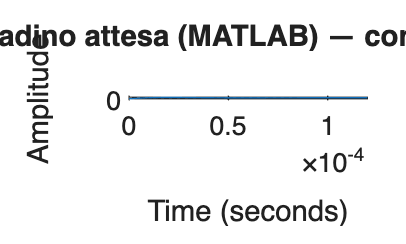

figure; step(CL_check*5);   % *5 per confrontare con l'ampiezza del tuo Step Simulink
title('Risposta al gradino attesa (MATLAB) — confronto con Simulink');

% Risposta al gradino (ampiezza 5V, griglia fine)
[y, t] = step(5 * CL_check);

% Estrai parametri con stepinfo
S = stepinfo(y, t, 'SettlingTimeThreshold', 0.02);

% --- Stampa risultati ---
fprintf('\n========== RISULTATI ==========\n');


========== RISULTATI ==========


fprintf('gamma* = %.6f\n', gamma_4w);

gamma* = 0.803832


fprintf('\nRisposta al gradino (ampiezza 5V):\n');


Risposta al gradino (ampiezza 5V):


fprintf('  Valore a regime:        %.4f V\n', mean(y(end-10:end)));

  Valore a regime:        4.9709 V


fprintf('  Sovraelongazione:       %.2f %%\n', S.Overshoot);

  Sovraelongazione:       30.05 %


fprintf('================================\n');

## Sezione 3.3 - Analisi mu

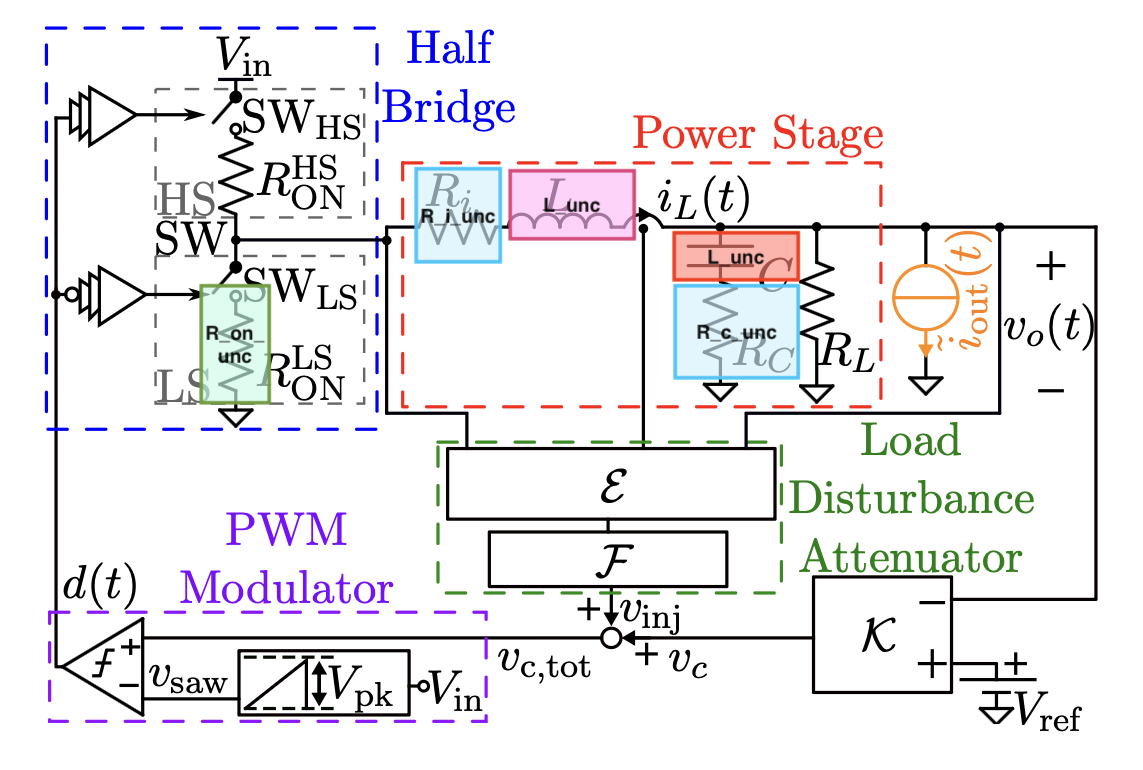

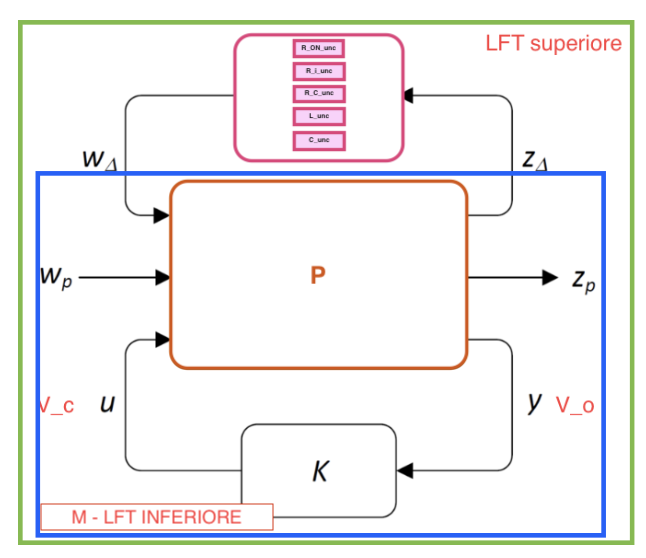

fprintf('--- SEZIONE 3.3: mu-analysis ---\n');

--- SEZIONE 3.3: mu-analysis ---



% Closed loop incerto
CL_unc = feedback(G_unc_use * K_4w, 1);

% Estrazione LFT (M_nom e blocco Delta)
[M_nom, Delta_unc, blkstruct] = lftdata(CL_unc);

% Dimensione del canale Delta
[ny_d, nu_d] = size(Delta_unc);
fprintf('  Dimensione blocco Delta: %d x %d\n', ny_d, nu_d);

  Dimensione blocco Delta: 11 x 11



% Estrazione M11 diretta (SENZA minreal per evitare errori con modelli impropri)
M11 = M_nom(1:ny_d, 1:nu_d);

% Calcolo della risposta in frequenza di M11 sul vettore omega_vec
M11_frd = freqresp(M11, omega_vec);

% Calcolo norma picco massima lungo la griglia di frequenze
norma_frq = zeros(length(omega_vec), 1);
for kf = 1:length(omega_vec)
    norma_frq(kf) = norm(M11_frd(:,:,kf), 2); % Norma spettrale a frequenza f
end
fprintf('  ||M11||_inf (calcolato su omega) = %.6f\n', max(norma_frq));

  ||M11||_inf (calcolato su omega) = 253.243288


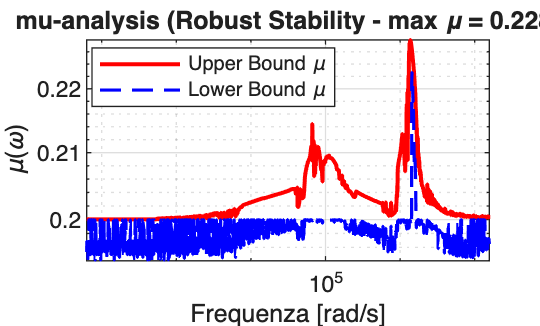


% Preallocazione vettori per mussv
mu_upper = zeros(size(omega_vec));
mu_lower = zeros(size(omega_vec));

% Calcolo della Mu-Analysis con mussv
for kf = 1:numel(omega_vec)
    Mjw = M11_frd(:,:,kf); % Estrazione matrice complessa alla frequenza w_k
    bnds = mussv(Mjw, blkstruct);
    
    % mussv: colonna 1 = Upper Bound, colonna 2 = Lower Bound
    mu_upper(kf) = bnds(1,1);
    mu_lower(kf) = bnds(1,2);
end

% Graphic Plot della Mu-Analysis
figure('Name','mu-analysis - Robust Stability','NumberTitle','off');
loglog(omega_vec, mu_upper, 'r-', 'LineWidth', 1.5); hold on;
loglog(omega_vec, mu_lower, 'b--', 'LineWidth', 1.2);
grid on;
legend('Upper Bound \mu', 'Lower Bound \mu', 'Location', 'best');
xlabel('Frequenza [rad/s]'); 
ylabel('\mu(\omega)');
title(sprintf('mu-analysis (Robust Stability - max \\mu = %.3f)', max(mu_upper)));
xlim([omega_vec(1) omega_vec(end)]);


fprintf('  max mu (da mussv) = %.4f\n', max(mu_upper));

  max mu (da mussv) = 0.2280



%% =========================================================
%  VERIFICA MEDIANTE robstab
% ==========================================================
[stabmarg, wcu, info] = robstab(CL_unc);

fprintf('\n=== RISULTATI ROBUST STABILITY (robstab) ===\n');


=== RISULTATI ROBUST STABILITY (robstab) ===


fprintf('  Margine di Incertezza (Lower/Upper) = [%.4f, %.4f]\n', ...
        stabmarg.LowerBound, stabmarg.UpperBound);

  Margine di Incertezza (Lower/Upper) = [4.4154, 4.4333]


fprintf('  mu equivalente (da robstab)          = %.4f\n', ...
        1 / stabmarg.LowerBound);

  mu equivalente (da robstab)          = 0.2265



if max(mu_upper) < 1.0
    fprintf('  ESITO: Il sistema e STABILE ROBUSTAMENTE (mu < 1).\n');
else
    fprintf('  ESITO: Attenzione! Esiste un''incertezza che destabilizza il sistema (mu >= 1).\n');
end

  ESITO: Il sistema e STABILE ROBUSTAMENTE (mu < 1).


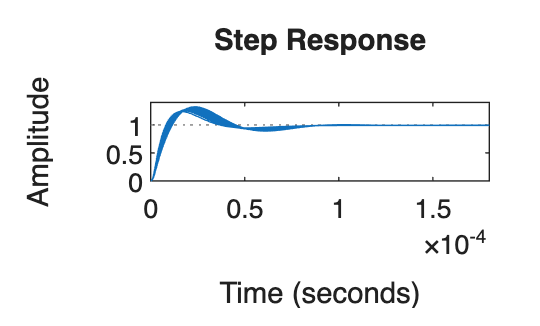

%Risposta al gradino del sistema incerto
figure;
step(CL_unc);

fprintf('--- SEZIONE 3.4: Performance Robuste tramite ultidyn ---\n');

--- SEZIONE 3.4: Performance Robuste tramite ultidyn ---



% 1. Estrai la matrice nominale M_nom_full e la blkstruct nativa di stabilità (RS)
[M_nom_full, Delta_unc, blkstruct_RS] = lftdata(CL_unc);

% 2. Calcola le dimensioni dei canali
[n_delta_y, n_delta_u] = size(Delta_unc); 
[n_total_y, n_total_u] = size(M_nom_full);

n_z = n_total_y - n_delta_y; % Uscite di performance
n_w = n_total_u - n_delta_u; % Ingressi di performance

fprintf('  Dimensione uscite di performance (z): %d\n', n_z);

  Dimensione uscite di performance (z): 1


fprintf('  Dimensione ingressi di performance (w): %d\n', n_w);

  Dimensione ingressi di performance (w): 1


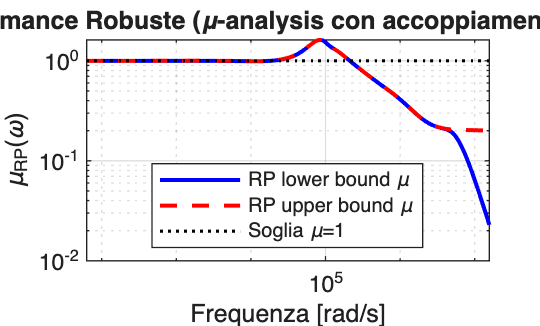


% 3. Crea il blocco fittizio usando ultidyn
Delta_P = ultidyn('Delta_P', [n_w, n_z], 'Bound', 1);

% 4. TRUCCO: Usiamo lftdata su Delta_P DA SOLO per farci dare la struct corretta da MATLAB!
[~, ~, blkstruct_P] = lftdata(Delta_P);

% Ora concateniamo le due strutture (essendo entrambe generate da lftdata, sono compatibili)
blkstruct_RP = [blkstruct_RS; blkstruct_P];

% 5. Ciclo di calcolo del mu sull'INTERA matrice M_nom_full originaria
mu_RP_lower = zeros(size(omega_vec));
mu_RP_upper = zeros(size(omega_vec));

for kf = 1:numel(omega_vec)
    % Valutiamo l'INTERA matrice nominale (quella che mappa sia Delta che Performance)
    Mjw_full = freqresp(M_nom_full, omega_vec(kf));
    
    % Ora le dimensioni di Mjw_full e blkstruct_RP coincidono perfettamente!
    bnds_RP = mussv(Mjw_full, blkstruct_RP);
    
    mu_RP_upper(kf) = bnds_RP(1,1);
    mu_RP_lower(kf) = bnds_RP(1,2);
end

% 6. Plot dei risultati
figure;
loglog(omega_vec, mu_RP_lower, 'b', omega_vec, mu_RP_upper, 'r--', 'LineWidth', 1.5);
hold on; loglog(omega_vec, ones(size(omega_vec)), 'k:', 'LineWidth', 1.2); grid on;
legend('RP lower bound \mu', 'RP upper bound \mu', 'Soglia \mu=1', 'Location','best');
xlabel('Frequenza [rad/s]'); ylabel('\mu_{RP}(\omega)');
title('Performance Robuste (\mu-analysis con accoppiamento struct)');
xlim([omega_vec(1) omega_vec(end)]);


max_mu_RP = max(mu_RP_upper);
fprintf('  max mu (Performance Robuste) = %.2f\n', max_mu_RP);

  max mu (Performance Robuste) = 1.62
